# DMRG: Two-site update for ground state search

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

In this tutorial, we will implement the two-site update DMRG method for ground state search.

## Exercise (a): Complete the two-site DMRG function

There is a function `DMRG_GS_2site_Ex.m`, which is in the same sub-directory with this script. It is incomplete. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`.

In the two-site update, you can decrease the bond dimensions by discarding ingular values smaller than $10^{-8}$ and their corresponding singular vectors as the *truncated* SVD. It is because the decreased bond dimensions can be increased back again, if needed, within the two-site update.

On the other hand, in the single-site update, bond dimensions cannot increase; so one should use the *thin* SVD (as opposed to the truncated SVD) that removes trivial zero contributions (coming from the mismatch between the row and column dimensions) only.

We revisit the XY spin chain to verify the code implementation. Here, we use a random MPS as the initial guess for both the single- and two-site updates, to compare their performance.

clear

% system parameter
J = -1; % coupling strength
L = 40; % number of sites in a chain

% DMRG parameter
Nkeep = 30; % bond dimension
Nsweep = 4; % number of pairs of left+right sweeps

% Local operators
[S,I] = getLocalSpace('Spin',1/2);

% % MPO formulation of Hamiltonian
% Hamiltonian tensor for each chain site
Hloc = cell(4,4);
Hloc(:) = {zeros(size(I))};
Hloc{1,1} = I;
Hloc{2,1} = S(:,:,1);
Hloc{3,1} = S(:,:,3);
Hloc{4,2} = J*S(:,:,1)';
Hloc{4,3} = J*S(:,:,3)';
Hloc{end,end} = I;
Hloc = cell2mat(reshape(Hloc,[1 1 size(Hloc,1) size(Hloc,2)]));

% full chain
Hs = cell(1,L);
Hs(:) = {Hloc};
Hs{1} = Hs{1}(:,:,end,:); % choose the last components of the left leg
Hs{end} = Hs{end}(:,:,:,1); % choose the first components of the right leg

Minit = cell(1,L);
Minit{1} = rand(1,Nkeep,size(I,2));
Minit{end} = rand(Nkeep,1,size(I,2));
for itN = (2:L-1)
    Minit{itN} = rand(Nkeep,Nkeep,size(I,2));
end

[M0_1site,E0_1site,Eiter_1site] = DMRG_GS_1site(Minit,Hs,Nkeep,Nsweep);

22-09-27 11:23:11 | Single-site DMRG: ground state search
22-09-27 11:23:11 | # of sites = 40, Nkeep = 30, # of sweeps = 4 x 2
22-09-27 11:23:11 | Sweep #1/8 (right -> left) : Energy = -12.52665
22-09-27 11:23:11 | Sweep #2/8 (left -> right) : Energy = -12.54658
22-09-27 11:23:11 | Sweep #3/8 (right -> left) : Energy = -12.55333
22-09-27 11:23:11 | Sweep #4/8 (left -> right) : Energy = -12.55389
22-09-27 11:23:11 | Sweep #5/8 (right -> left) : Energy = -12.5539
22-09-27 11:23:12 | Sweep #6/8 (left -> right) : Energy = -12.5539
22-09-27 11:23:12 | Sweep #7/8 (right -> left) : Energy = -12.5539
22-09-27 11:23:12 | Sweep #8/8 (left -> right) : Energy = -12.5539
Elapsed time: 1.211s, CPU time: 13.1s, Avg # of cores: 10.81


[M0_2site,E0_2site,Eiter_2site] = DMRG_GS_2site_Ex(Minit,Hs,Nkeep,Nsweep);

22-09-27 11:23:12 | Two-site DMRG: ground state search
22-09-27 11:23:12 | # of sites = 40, Nkeep = 30, # of sweeps = 4 x 2
22-09-27 11:23:12 | Sweep #1/8 (right -> left) : Energy = -12.53001
22-09-27 11:23:12 | Sweep #2/8 (left -> right) : Energy = -12.54921
22-09-27 11:23:13 | Sweep #3/8 (right -> left) : Energy = -12.55367
22-09-27 11:23:13 | Sweep #4/8 (left -> right) : Energy = -12.5539
22-09-27 11:23:13 | Sweep #5/8 (right -> left) : Energy = -12.5539
22-09-27 11:23:13 | Sweep #6/8 (left -> right) : Energy = -12.5539
22-09-27 11:23:14 | Sweep #7/8 (right -> left) : Energy = -12.5539
22-09-27 11:23:14 | Sweep #8/8 (left -> right) : Energy = -12.5539
Elapsed time: 1.892s, CPU time: 21.12s, Avg # of cores: 11.16


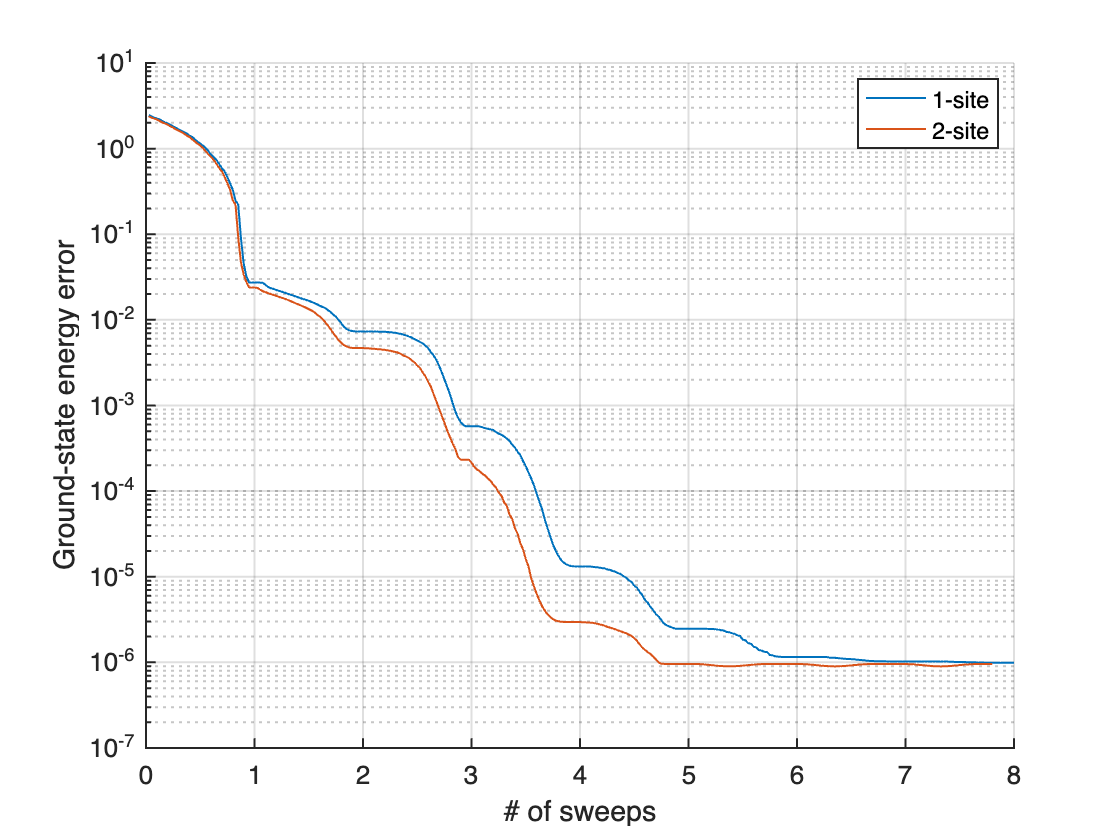

E0_exact = 0.5 - (1/2/sin(pi/2/(L+1))); % exact value

figure;
hold on;
plot((1:numel(Eiter_1site))/L,Eiter_1site(:)-E0_exact,'LineWidth',1);
plot((1:numel(Eiter_2site))/L,Eiter_2site(:)-E0_exact,'LineWidth',1);
hold off;
set(gca,'XScale','Linear','YScale','log','FontSize',13,'LineWidth',1);
xlim([0 2*Nsweep]);
grid on;
xlabel('# of sweeps');
ylabel('Ground-state energy error');
legend({'1-site','2-site'})

For most cases, the two-site update better converges to the solution in terms of number of sweeps. At each iteration, the bond space between the two tensors that are updated is identified by SVD-ing a rank-4 tensor given by the Lanczos solution of the effective Hamiltonian. The bond space can be optimized by exploring larger space (of dimension $Dd$ in the standard naming convention, or `Nkeep*size(I,2)` in this code) and then truncating it. By contrast, in the single-site update, the bond spaces are fixed, as they are also spanned by the right and left legs of the left and right neighbor tensors (that are fixed in the current iteration), respectively.

Of course, the two-site update takes more computational cost than the single-site update; see the time lap record above. Therefore, it is desirable to have a method having a better convergence behavior as the two-site update while having a cheaper computational cost comparable to the single-site update.

## Exercise (b): Majumdar-Ghosh model

In this Exercise, we consider another spin chain model. The Majumdar-Ghosh model is a spin-1/2 chain with the nearest-neighbor and next-nearest-neighbor interactions,


$$\hat{H} = \sum_{\ell=1}^{L-1} \hat{\vec{S}}_\ell \cdot \hat{\vec{S}}_{\ell+1} + \frac{1}{2} \sum_{\ell=1}^{L-2} \hat{\vec{S}}_\ell \cdot \hat{\vec{S}}_{\ell+2} .$$


The model has an analytic solution of the ground state, which has energy $-3L/8$.

Compute the ground state of this system by using the two-site update DMRG and compare the numerical ground-state energy with the exact value. Once you look into the output MPS, you will find a peculiarity of the ground state. Explain the peculiarity by plotting the singular values (obtained as the fourth output of `DMRG_GS_2site_Ex.m`.) and computing the spin-spin correlation function $\langle \hat{S}_{\ell,+} \hat{S}_{\ell+1,-} \rangle$

(Hint: see Eqs. (184) and (185) of [[U. Schollwöck, Ann. Phys. **326**, 96 (2011)](https://www.sciencedirect.com/science/article/pii/S0003491610001752?via%3Dihub)] to find an MPO representation of the Hamiltonian with the nearest-neighbor and next-nearest-neighbor interactions.)